# **相控天线阵的动态演示（利用实时脚本等解析计算）**

**        相控天线阵是一种利用相位控制技术的天线系统，它由多个天线单元组成，并能够通过调整每个天线单元的相位来控制信号的方向和形状。这种技术使得相控天线阵能够实现波束的形成和指向性辐射，从而在通信、雷达和无线电等领域发挥重要作用。**

**        根据**[**上一小节**](matlab:open('./G3_Antenna_Array.mlx'))**的的理论分析，可以运用 MATLAB 仿真完成进一步的分析，例如给出天线阵方向图随各参数的变化动态，程序如下。 **

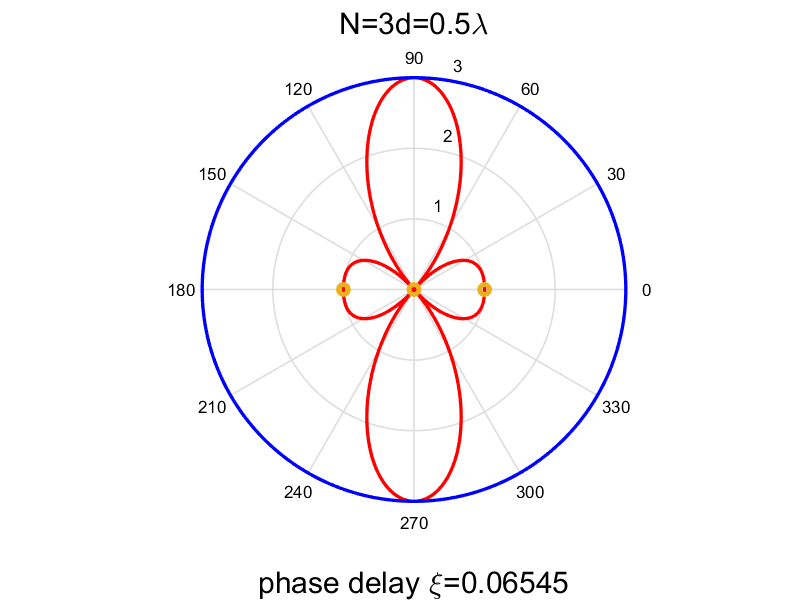

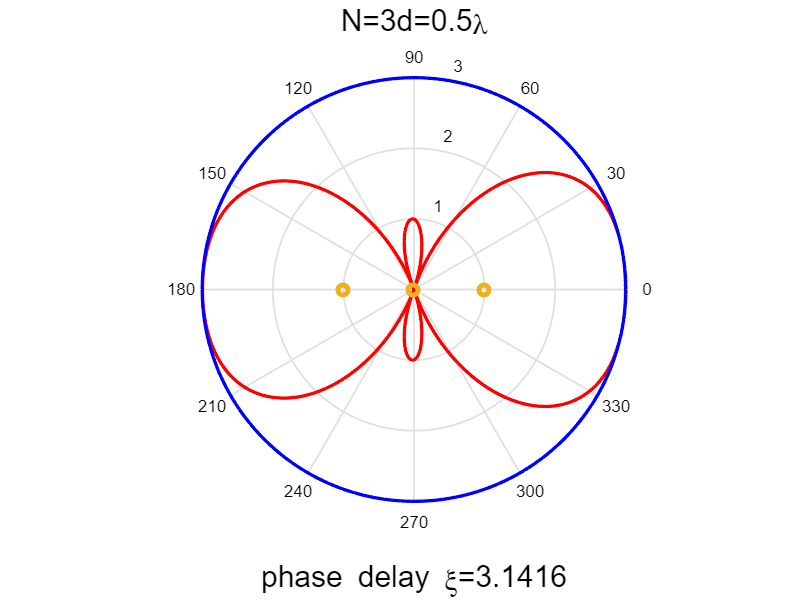

clc
clear
N=3;                                  %偶极子个数
lambda=1;
d=0.5*lambda;
xi=pi;                                %天线单元的相位差
dip=[1:N];
k=2*pi/lambda;                        %波数
phi=[0:2*pi/800:2*pi];                %方位角
framemax=48;
M=moviein(framemax);                  %moviein(n)函数用来建立一个足够大的n列矩阵，该矩阵用来保存n幅画面的数据，以备播放
set(gcf,'Position',[100 100 640 480]) %设置绘图的大小，将图像设置为距屏幕
                                      %左下角[100，100]，图像大小设置为640×480像素
for n=1:framemax
    u=k*d*cos(phi)-xi/framemax*(n-1); %[0:pi]
    F=abs(sin(N*(u/2))./sin(u/2));    %阵因子
    pp=polar(phi,abs(F),'r');         %绘制极坐标图
    set(pp,'LineWidth',2);
    title(['N=',num2str(N),'d=',num2str(d),'\lambda'],'fontsize',18);
                                      %lambda是图形名称
    xlabel(['phase delay \xi=',num2str(xi/framemax*(n))],'Color','k','FontSize',18);
                                      %num2str将数值转化为字符串
    hold on;
    plot(N*cos(phi),N*sin(phi),'b','LineWidth',2);
                                      %N为阵因子的最大值
    plot(dip-N/2-0.5,dip*0,'o','linewidth',3)
                                      %画三个偶极子的位置（-0.5,0）（+0.5,0）
    axis equal;                       %横纵坐标采用等长刻度
    mov(n)=getframe(gcf);             %截取一幅画面信息（称为画面中的一帧）
                                      %一幅画面信息形成一个很大的列向量
    pause(0.01);
    hold off;
end

- **动态展示**

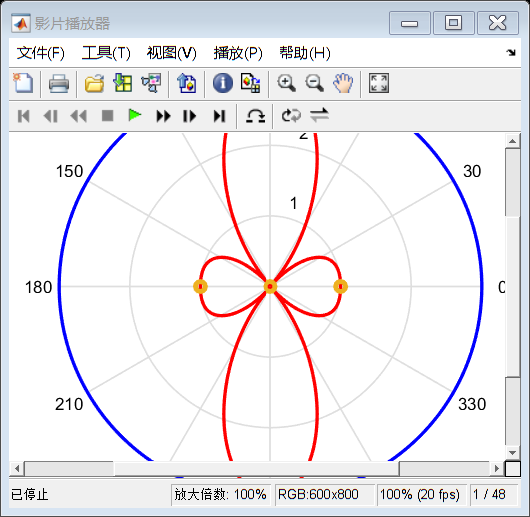

implay(mov);

- **保存为视频文件**

v=VideoWriter('相控天线阵.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)